# visualizing b_sec at one time - 2d

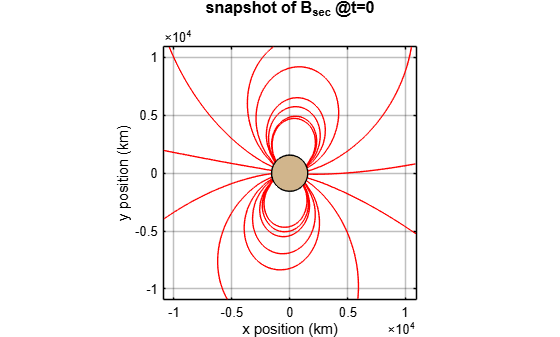

clear
% define constants

r_m = 1560; % Europa radius (km)
B_prim = 250; % approximate background field AMPLITUDE nT
A = 0.95; % amplitude response factor
phi = 0.14; % phase lag in radians (around 8 deg)
omega = 2*pi / (11.23 * 3600); % synodic freq. (rad/sec), 11.23 hr period

t = 0; % taking a snapshot

% inducing field direction
e0x = [1;0;0];
e0y = [0;1;0];
% bz is constant, so no change in background field in z means no induction
% response, so there is no e0z

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% create spatial grid (x-y plane)
grid_limit = 7 * r_m; % view up to 7 planetary radii out 
[X,Y] = meshgrid(linspace(-grid_limit, grid_limit, 30), ...
    linspace(-grid_limit,grid_limit, 30));

Z = zeros(size(X)); % slicing through z=0

% compute secondary field components (bx,by,bz) at every point 
% initialize arrays to hold magnetic field vector components

Bx_spatial = zeros(size(X));
By_spatial = zeros(size(X));
Bz_spatial = zeros(size(X));


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% loop through each grid point to calculate the spatial part of eqn (3)
for i = 1:numel(X)

    % define position vector r from center of moon
    r_vec = [X(i); Y(i); Z(i)];
    r = norm(r_vec);

    % mask field inside the moon to avoid division by 0
    if r < r_m
        continue;
    end


    % X EQUATION
    % calculate dot prod (r . e0x)
    r_dot_e0x = dot(r_vec, e0x);

    % evaluate spatial vector bracket: 3*(r . e0)*r - (r^2)*e0
    spatial_bracketx = 3 * r_dot_e0x * r_vec - (r^2) * e0x;

    % compute spatial coefficient: - (A * B_prim * r_m^3) / (2 * r^5)
    coefx = - (A * B_prim * r_m^3) * (cos (omega * t - phi)) / (2 *r^5);


    % Y EQUATION
    % calculate dot prod (r . e0y)
    r_dot_e0y = dot(r_vec, e0y);

    % evaluate spatial vector bracket: 3*(r . e0)*r - (r^2)*e0
    spatial_brackety = 3 * r_dot_e0y * r_vec - (r^2) * e0y;

    % compute spatial coefficient: - (A * B_prim * r_m^3) / (2 * r^5)
    coefy = - (A * B_prim * r_m^3) * (sin (omega * t - phi)) / (2 *r^5);



    % store vector components
    B_vector = (coefx * spatial_bracketx) + (coefy * spatial_brackety);
    Bx_spatial(i) = B_vector(1);
    By_spatial(i) = B_vector(2);
    Bz_spatial(i) = B_vector(3);    

end



Bx = Bx_spatial;
By = By_spatial;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% create static figure
figure('Color','w');
hold on;


% seeds of the streamlines

theta = linspace(0, 2*pi, 20); % 20 angles around a circle
seed_x = 3 * r_m * cos(theta); % circle just outside Europa's radius
seed_y = 3 * r_m * sin(theta);

% plot mag field vectors
h1 = streamline(X,Y,Bx,By,seed_x, seed_y);
h2 = streamline(X,Y,-Bx,-By,seed_x, seed_y);

% draw Europa as filled circle
rectangle('Position',[-r_m, -r_m, 2*r_m, 2*r_m], 'Curvature', [1,1], ...
    'FaceColor', [0.82 0.71 0.55], 'EdgeColor','k');


set(h1, 'Color', 'r', 'LineWidth', 0.5);
set(h2, 'Color', 'r', 'LineWidth', 0.5);




% grid formatting
axis equal; 
xlim([-grid_limit, grid_limit]);
ylim([-grid_limit, grid_limit]);
xlabel('x position (km)', 'FontSize', 11);
ylabel('y position (km)', 'FontSize', 11);
title('snapshot of B-sec @t=0 (X-Y)', 'FontSize', 12);
grid on;
box on;



ax = gca;
set(ax, 'Position', [0.13, 0.11, 0.775, 0.75], 'XColor', 'k', 'YColor', 'k', 'ZColor', 'k', 'Color', 'w'); 
% [left, bottom, width, height]


t1 = title('snapshot of B_s_e_c @t=0', 'FontSize', 12, 'Color', 'k');
t1.Units = 'normalized';
t1.Position(2) = 1.10;